clc
clear
addpath("srcs\all_func\");
% Step 1: Load and preprocess the image data
class1Dir = 'srcs/imgs/Aneurysm';  % Directory containing aneurysm images
class2Dir = 'srcs/imgs/Normal';  % Directory containing non-aneurysm images

class1Files = imageDatastore(class1Dir);  % Assuming images are in JPEG format
class2Files = imageDatastore(class2Dir);

imageData = cell(0);  % Initialize an empty cell array to store the image data
labels = [];    % Initialize an empty vector to store the labels

% Load and preprocess aneurysm images (class 1)
for i = 1:numel(class1Files.Files)
    img = readimage(class1Files, i);
    % Preprocess the image if necessary (e.g., resize, normalize, etc.)
    img = imresize(img, [500, 500]);
    img = AllFilters.imagePrepare(img);
    img = AllFilters.medFilter(img);
    img = AllFilters.imClose(img);
    % Add the preprocessed image to the imageData cell array and assign class 1 label
    imageData{end+1} = img;
    labels = [labels; 1];
end


% Load and preprocess non-aneurysm images (class 2)
for i = 1:numel(class2Files.Files)
    img = readimage(class2Files, i);
    % Preprocess the image if necessary (e.g., resize, normalize, etc.)
    img = imresize(img, [500, 500]);
    img = AllFilters.imagePrepare(img);
    img = AllFilters.medFilter(img);
    img = AllFilters.imClose(img);
    % Add the preprocessed image to the imageData cell array and assign class 2 label
    imageData{end+1} = img;
    labels = [labels; 2];
end

% Convert cell array to matrix
numImages = numel(imageData);
imageDataMatrix = zeros(numImages, numel(imageData{1}(:)));
for i = 1:numImages
    imageDataMatrix(i, :) = imageData{i}(:)';
end


n = 1000;
accuracies = zeros([1 n]);
for i=1:n

    % Step 2: Split the data into training and testing sets
    c = cvpartition(labels, 'HoldOut', 0.2);  % 80% for training, 20% for testing
    trainIdx = training(c);
    testIdx = test(c);
    trainData = imageDataMatrix(trainIdx, :);
    trainLabels = labels(trainIdx);
    testData = imageDataMatrix(testIdx, :);
    testLabels = labels(testIdx);


    % Step 3: Train the KNN classifier
    k = round(sqrt(sum(trainIdx)));  % Set the number of nearest neighbors
    %k = 1;
    mdl = fitcknn(trainData, trainLabels, 'NumNeighbors', k);

    % Step 4: Classify the test data
    predictedLabels = predict(mdl, testData);


    % Step 5: Evaluate the classification accuracy
    accuracies(i) = sum(predictedLabels == testLabels) / numel(testLabels);
end

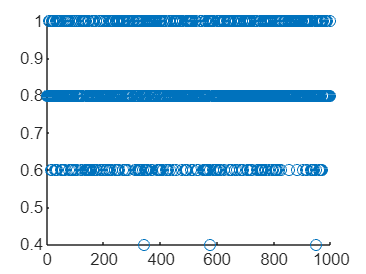

scatter(1:n, accuracies)

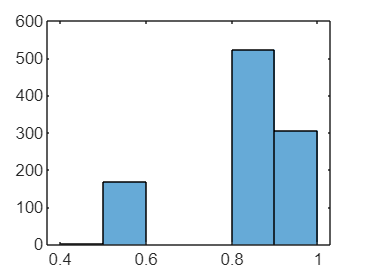

histogram(accuracies, BinWidth=0.1)

fprintf('Classification Accuracy: %.2f%%\n', sum(accuracies) / n * 100);

Classification Accuracy: 82.64%


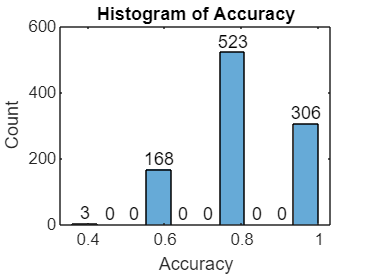

% Numeric array (1 x n)
data = [1, 2, 3, 4, 5, 5, 6, 7, 7, 7, 8, 9, 9, 9, 10];

% Number of bins for the histogram
numBins = 10;

% Plot histogram
figure;
histogram(accuracies, numBins);
title('Histogram of Accuracy');
xlabel('Accuracy');
ylabel('Count');

% Get the bin counts and bin edges
[binCounts, binEdges] = histcounts(accuracies, numBins);

% Display the count on each bin
for i = 1:numBins
    text((binEdges(i)+binEdges(i+1))/2, binCounts(i), num2str(binCounts(i)), ...
        'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');
end